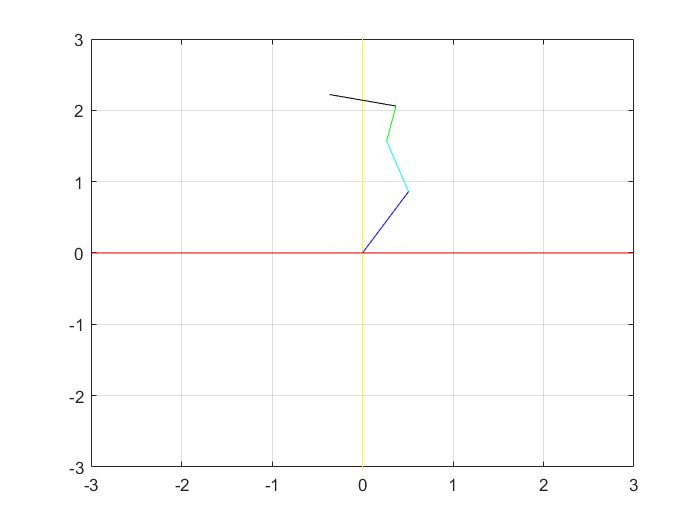

clc;
clear all;

a1=1; a2=0.75; a3=0.5; a4=0.75;

%dof
theta1DegMin = 30; theta1DegMax = 60;
theta2DegMin = 20; theta2DegMax = 50;
theta3DegMin = -60; theta3DegMax = -30;
theta4DegMin = 60; theta4DegMax = 90;

%min
theta1Min = theta1DegMin*pi/180;
theta2Min = theta2DegMin*pi/180;
theta3Min = theta3DegMin*pi/180;
theta4Min = theta4DegMin*pi/180;

%max
theta1Max = theta1DegMax*pi/180;
theta2Max = theta2DegMax*pi/180;
theta3Max = theta3DegMax*pi/180;
theta4Max = theta4DegMax*pi/180;

%no of steps
n = 50;

deltaTheta1 = (theta1Max-theta1Min)/n;
deltaTheta2 = (theta2Max-theta2Min)/n;
deltaTheta3 = (theta3Max-theta3Min)/n;
deltaTheta4 = (theta4Max-theta4Min)/n;

theta1 = theta1Min; theta2 = theta2Min; 
theta3 = theta3Min; theta4 = theta4Min;

aXArray = zeros(n,1);   aYArray = zeros(n,1); 
bXArray = zeros(n,1);   bYArray = zeros(n,1);
cXArray = zeros(n,1);   cYArray = zeros(n,1);
dXArray = zeros(n,1);   dYArray = zeros(n,1);

for i=1:n
    
    ax = a1*cos(theta1);
    ay = a1*sin(theta1);
    bx = ax + a2*cos(theta1+theta2);
    by = ay + a2*sin(theta1+theta2);
    cx = bx + a3*cos(theta1+theta2+theta3);
    cy = by + a3*sin(theta1+theta2+theta3);
    dx = cx + a4*cos(theta1+theta2+theta3+theta4);
    dy = cy + a4*sin(theta1+theta2+theta3+theta4);
    
    aXArray(i) = ax;    aYArray(i) = ay;
    bXArray(i) = bx;    bYArray(i) = by;
    cXArray(i) = cx;    cYArray(i) = cy;
    dXArray(i) = dx;    dYArray(i) = dy;
    
    theta1 = theta1+deltaTheta1;
    theta2 = theta2+deltaTheta2;
    theta3 = theta3+deltaTheta3;
    theta4 = theta4+deltaTheta4;
end

    xAxisArrayXCoords = [-3,3];
    xAxisArrayYCoords = [0,0];
    
    yAxisArrayXCoords = [0,0];
    yAxisArrayYCoords = [-3,3];
    
%Animatiom
for i = 1:1:n
    
    ax = aXArray(i); ay = aYArray(i);
    bx = bXArray(i); by = bYArray(i);
    cx = cXArray(i); cy = cYArray(i);
    dx = dXArray(i); dy = dYArray(i);
    
    link1Xcords = [0 ax];
    link1Ycords = [0 ay];
    link2Xcords = [ax bx];
    link2Ycords = [ay by];
    link3Xcords = [bx cx];
    link3Ycords = [by cy];
    link4Xcords = [cx dx];
    link4Ycords = [cy dy];        
    
    plot(xAxisArrayXCoords, xAxisArrayYCoords, 'r',yAxisArrayXCoords, yAxisArrayYCoords,'y');
    grid on;
    hold on;
    plot(link1Xcords,link1Ycords,'b',link2Xcords,link2Ycords,'c',link3Xcords,link3Ycords,'g',link4Xcords,link4Ycords,'k');
    hold off;
    pause(0.01);
    
end